# Fit multiline LIF images set

*Use loadTIFImages.mlx or supply a scan settings file as described*

init;

% Author: Abbas El Moussawi
% COPYRIGHT 2024: EMPI-RF - University of Duisburg-Essen  

#### Scan setting file

measurementsFolder = "D:\Cloud\OneDrive - Universitaet Duisburg-Essen\06_dev\git\LIFSim4.0\input-data\exampleImagedSpectra\MATLAB_out"; 


everything = dir(measurementsFolder);
folderIndex = [everything.isdir];
allFolders = everything(folderIndex);
if length(allFolders) == 2
    error('Directory is empty!')
end

measurements = {allFolders(3:end).name};
measurements = string(measurements);


measurementFolder = fullfile(measurementsFolder,measurements(1)); 
allSettings = dir(fullfile(measurementFolder,'*_scan.settings.mat'));

if isempty(allSettings)
    error('Directory is empty!')
end

settingFiles = {allSettings.name};
settingFiles = string(settingFiles);

settingsPath = fullfile(measurementFolder, settingFiles(1));


load(settingsPath, "scan");

fprintf('Loaded settings: %s\n', settingsPath)

Loaded settings: D:\Cloud\OneDrive - Universitaet Duisburg-Essen\06_dev\git\LIFSim4.0\input-data\exampleImagedSpectra\MATLAB_out\FOR0064\20240905-092436_scan.settings.mat


fprintf('Species: %s, wavenumbers: %.2f–%.2f 1/cm\n', scan.species, scan.startWN, scan.endWN)

Species: NO, wavenumbers: 44402.00–44417.00 1/cm



h = scan.h;
w = scan.w;

*Line list version (must be under /input-data/lines/)*

listVersion = "";

#### **Pressure and collisions data**

*(Support for NO, otherwise update function 'collissions')*

P = 0.03;

dnuL = 0.01;
dnuShC = 0;

[linelist, Z, n,~,MM, emList] = selectLines(scan.species,scan.wavenumbers, listVersion=listVersion, outside=5);
linelistNotShifted = linelist;

if n == 0
    warning("No lines found.")
    return;
end

colls =  collisions(scan.species);
gas = {};
if ~isempty(colls)
    path = "D:\Cloud\OneDrive - Universitaet Duisburg-Essen\06_dev\git\LIFSim4.0\input-data\gas-compositions\gas-composition-example_phi-0.6.csv";
    gas = loadGasComposition(path);
end

**Detection filter**

    Keep empty to ignore filter

pathFilter = "D:\Cloud\OneDrive - Universitaet Duisburg-Essen\06_dev\git\LIFSim4.0\input-data\filters\NO.Notch.20deg.csv";
filterUnit = 'nm';
filter = 0;
nmFilter = 0;
if isfile(pathFilter)
    [filter, nmFilter] = loadSpectrum(pathFilter,filterUnit);
    [linelist,emList] = fluorTransm(linelist, emList, filter);
end


#### Pixel initialization

*Masking on mean LIF intensity threshold*

images3d = double(cat(3, scan.imgs{:}));
close all
threshold = 0.05;

*Mask on region of interest*


ROI = [11 10 ...
    58 80];
if ROI(1)<1 || ROI(1)>h, ROI(1) = 1; end
if ROI(2)<1 || ROI(2)>w, ROI(2) = 1; end
if ROI(3)<1 || ROI(3)>h, ROI(3) = h; end
if ROI(4)<1 || ROI(4)>w, ROI(4) = w; end

mask = false(size(scan.meanimg));
roiMask = mask;
roiMask(ROI(1):ROI(3), ROI(2):ROI(4)) = true;

roiCond = (scan.meanimg -min(scan.meanimg(:))) > threshold*(max(scan.meanimg(:)));
roiCond = roiCond & roiMask;

mask(roiCond) = true;


*Starting position*

  pixelSelection = 1;


startX=round(scan.w/2);
startY= round(scan.h/2);

if pixelSelection == 2

        If opted for 'User input' 

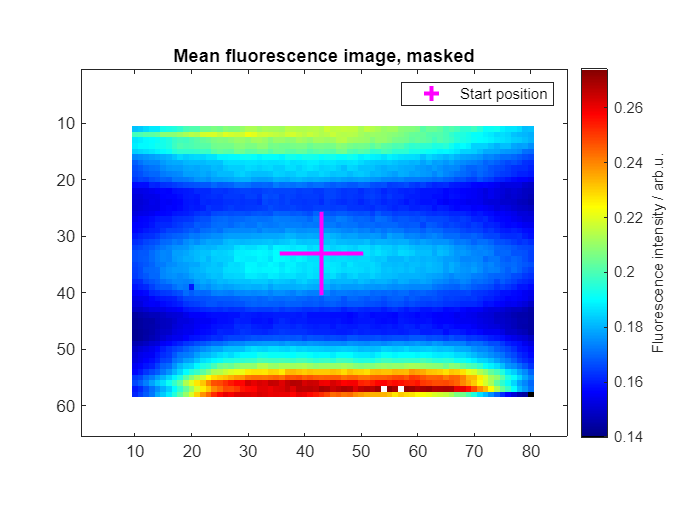

    startPx = [109 59 ];

    try
        mask(startPx(1), startPx(2));
        startX=startPx(2);
        startY= startPx(1);
    catch
        error('Chosen position is out image bounds!')
    end
end

for i=1:2
    figMean = figure;
mm = scan.meanimg;
mm(~mask) = Inf;
    imagesc(mm);
    title   ('Mean fluorescence image, masked');
    axis image;
    colorbarJet(figMean, label='Fluorescence intensity / arb.u.');
    
hold on;
plot(startX,startY, 'm+', 'MarkerSize', 50, 'LineWidth', 2.5,DisplayName='Start position');
legend show
    if pixelSelection < 3
        break;
    end
    if i==1
        set(figMean,"Visible","off");
        try
            title   ('Select starting position');
            [x,y]=ginput(1);
            startX=round(x);
            startY= round(y);

            set(figMean,"Visible","off");
        catch
            warning('Nothing selected! Center pixel taken.')
        end
    end
end


if ~mask(startY, startX)
    error('Chosen pixel position is masked out, change mask or pixel position');
end
fprintf('Starting pixel Y=%d, X=%d \n', startY,startX);

Starting pixel Y=33, X=43 


pixelCount = sum(mask(:));
fprintf('%i pixels to fit\n', pixelCount)

3408 pixels to fit



max3dImgs = max(images3d, [], 3);
max3dImgs = repmat(max3dImgs, [1, 1, size(images3d, 3)]);

normImages3d = images3d./max3dImgs;

startSpec = normImages3d(startY,startX,:);
startSpec = startSpec(:);

#### Initial fit parameters

bounds = zeros(1,7);
T = 1400; bounds(1) = 500;% K
dnuGL = 0.3; bounds(2) = 0.7; % 1/cm 
dnuLL = 0.21; bounds(3) = 0.5;% 1/cm 

*The spectra will be normalized before fitting*

scale = 1; bounds(4) = 0.15;% to norm
bounds(4) = bounds(4)*scale/100;

*If collissions are set, the collisional shift is added to this value:*

dnuSh = -0.65; bounds(5) = 0.4;% 1/cm 
offset = 0; bounds(6) = 0.36;% -
slope = 0; bounds(7) = 0.011;% -

*Single line shift*

lineShifting = true;
lineFitRegions =  [44414 44417] ;


        *e.g.  [44402 4445; 44414 44417]  *

boundShift = 0.25;

startParams = [
    T,    ...  %T
    dnuGL,...  %dnuGL
    dnuLL,...  %dnuLL
    scale,...  %scale
    dnuSh,...  %shift
    offset,... %offset
    slope% baseline slope
    ];


#### Preview spectrum for selected pixel vs. simulation of initial parameters

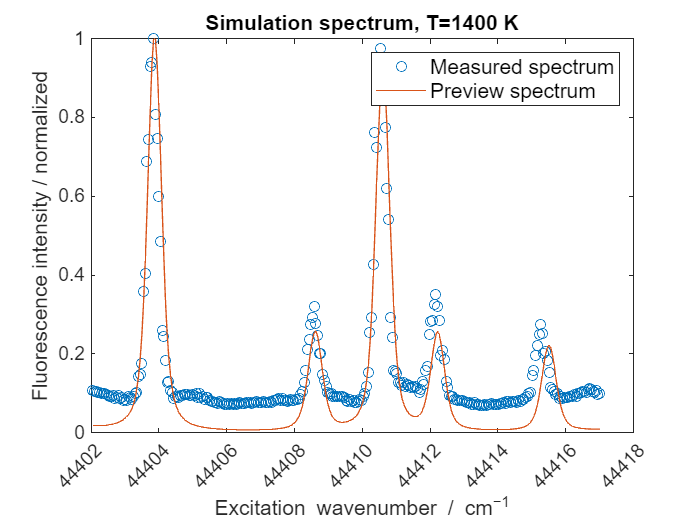

 

prefit = excitationSpecSolution(scan.wavenumbers, linelist, MM, startParams, Z= Z, colls=colls, gas=gas, P=P);

figure;
plot(scan.wavenumbers, startSpec, 'o', DisplayName='Measured spectrum')

title(['Simulation spectrum, T=' num2str(startParams(1)) ' K'])
hold on;



plot(scan.wavenumbers, prefit, DisplayName='Preview spectrum' )
legend;
LABELS('1/cm');
LABELS("flourIntNorm");

% drawnow;


#### Fitting spectrum at starting position

verbose = true;

 
options = getFitOptions(id="lsqnonlin");

if ~verbose
    options.Display = "none";
end

bestFit = startParams;
   
for i = 1:2

    t = tic;

lb = bestFit- bounds;
ub = bestFit+ bounds; 


    [bestFit, residue] = fitExcitationSpec(scan.wavenumbers, startSpec, linelist, MM, bestFit,  options,lb=lb, ub=ub,Z=Z, colls=colls, gas=gas, P=P);
    t = toc(t);
    if ~lineShifting || i>1
        break;
    end
    linelist = linesShiftCorrection(...
        linelistNotShifted, scan.wavenumbers, startSpec, bestFit, MM, Z=Z, colls=colls, gas=gas, P=P,...
        fitRegions = lineFitRegions, verbose = verbose, boundary=boundShift);

end


Optimization stopped because the relative sum of squares (r) is changing
by less than options.FunctionTolerance = 1.000000e-05.




Optimization stopped because the relative sum of squares (r) is changing
by less than options.FunctionTolerance = 1.000000e-05.

11. 
Shifted Q12, delta: 44416.0742 - 44415.8709 = 0.20331
12. 
Shifted P2, delta: 44416.1758 - 44416.0022 = 0.17356
Residue: 0.16991



Optimization stopped because the relative sum of squares (r) is changing
by less than options.FunctionTolerance = 1.000000e-05.





  

disp(['Residue: ' num2str(residue)])

Residue: 0.17103


[fitSpec, collEffect] = excitationSpecSolution(scan.wavenumbers, linelist, MM, bestFit, Z= Z, colls=colls, gas=gas, P=P);

disp(fitParamStr(bestFit))

1. T: 1281.34 K
2. dnuGL: 0.2 1/cm
3. dnuLL:0.14 1/cm
4. Scale:1
5. dnuSh:-0.71 1/cm
6. Offset:0.07
7. Slope:0


if ~isempty(colls)
    disp('Collision effects:')
    disp(['dnuShC: ' num2str(collEffect.dnuShC) ' 1/cm'])
    disp(['dnuL: ' num2str(collEffect.dnuL) ' 1/cm'])
end

Collision effects:


dnuShC: -0.0023112 1/cm


dnuL: 0.0063037 1/cm


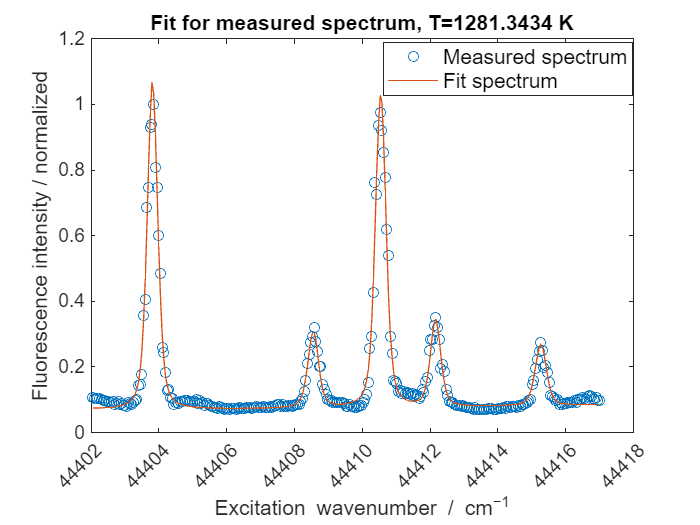


figure, plot(scan.wavenumbers, startSpec, 'o', DisplayName='Measured spectrum')
title(['Fit for measured spectrum, T=' num2str(bestFit(1)) ' K'])
hold on;


plot(scan.wavenumbers, fitSpec, DisplayName='Fit spectrum')

legend;
LABELS('1/cm');
LABELS("flourIntNorm");

legend("Position", [0.5481 0.8187 0.3554, 0.1012])

% drawnow;
return;

### Start parallel fitting

 
showProgress = true;
tt = tic;
[fittedImage, fitResidue, tempFig] = ...
    fitExcImageDataset(scan.wavenumbers, normImages3d,MM, linelist, ...
    [startY startX], bestFit,mask, options, showProgress,bounds,...
    'Z', Z, 'gas', gas,'P', P, 'colls', colls);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


tt = toc(tt);
fprintf('Real time elapsed: %.2f s.\n', tt);
ts2 = getTimeStamp;

return;

Save results

 

exportto = fullfile(fileparts(settingsPath), [ts2 '_fitResults.mat']);



save(exportto, 'fittedImage', 'fitResidue', 'scan',"images3d", "MM","linelist",...
    "startX", "startY", "bestFit", "showProgress","mask","options",...
    'Z', 'bounds','gas','P','colls', 'settingsPath', 'normImages3d', 'max3dImgs', 'linelistNotShifted');
fprintf('Results exported to: %s.\n', exportto)
winopen(fileparts(settingsPath));
return;